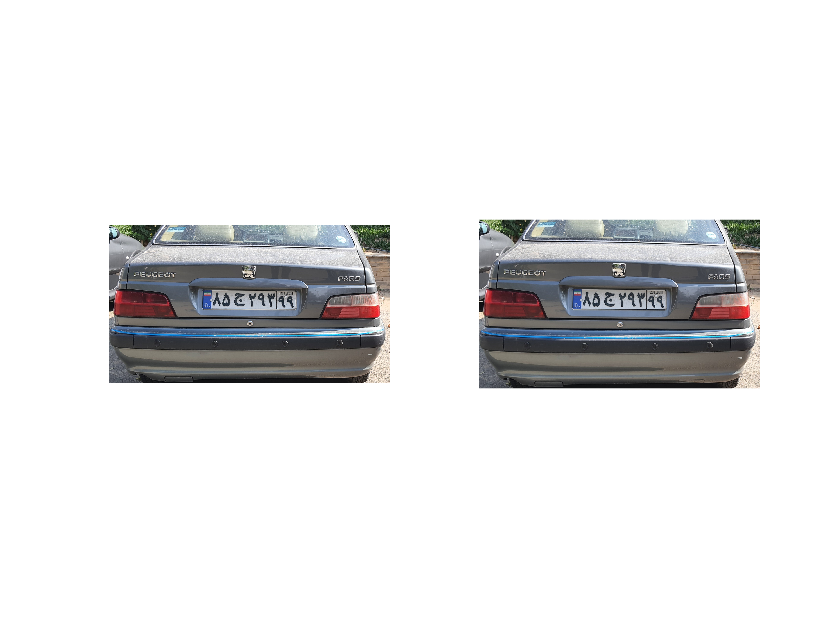


clc
close all;
clear;
load TRAININGSET;
totalLetters=size(TRAIN,2);



% SELECTING THE TEST DATA
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
[file,path]=uigetfile({'*.jpg;*.bmp;*.png;*.tif'},'Choose an image');
s=[path,file];
picture=imread(s);
figure
subplot(1,2,1)
imshow(picture)
picture=imresize(picture,[600 1000]);
subplot(1,2,2)
imshow(picture)

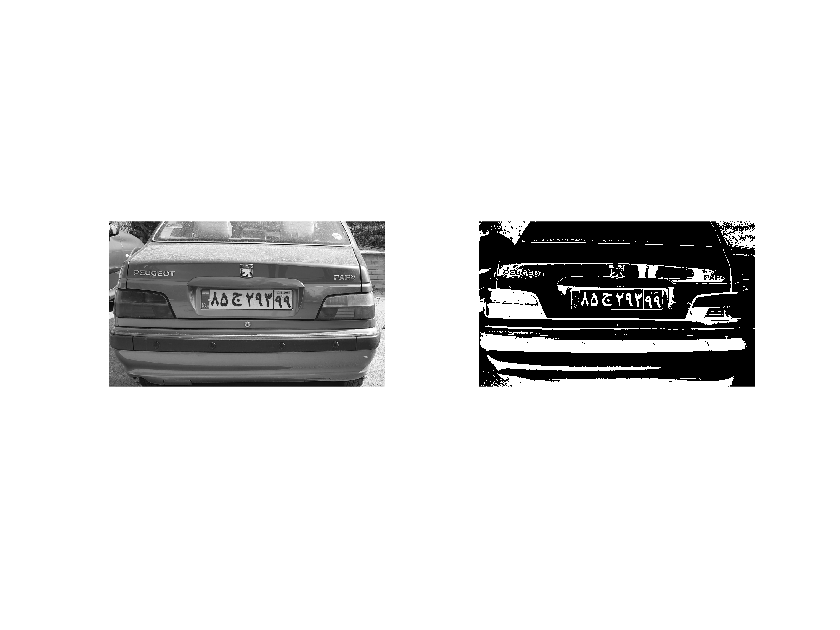



%RGB2GRAY
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
picture=rgb2gray(picture);
figure
subplot(1,2,1)
imshow(picture)

% THRESHOLDIG and CONVERSION TO A BINARY IMAGE
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
threshold = graythresh(picture);
picture =~imbinarize(picture,0.3);
subplot(1,2,2)
imshow(picture)

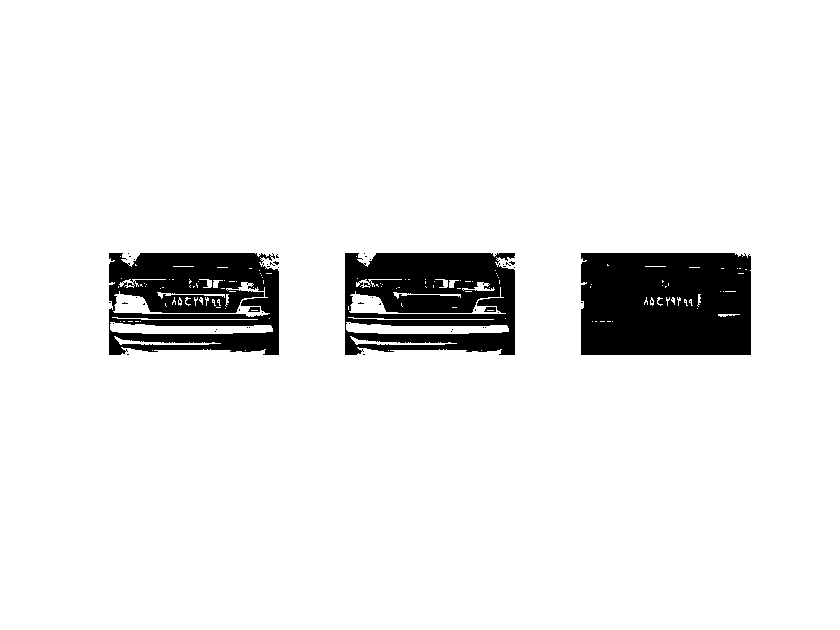


% Removing the small objects and background
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
picture = bwareaopen(picture,80);
subplot(1,3,1)
imshow(picture)
background=bwareaopen(picture,2000);
subplot(1,3,2)
imshow(background)
picture2=picture-background;
subplot(1,3,3)
imshow(picture2)

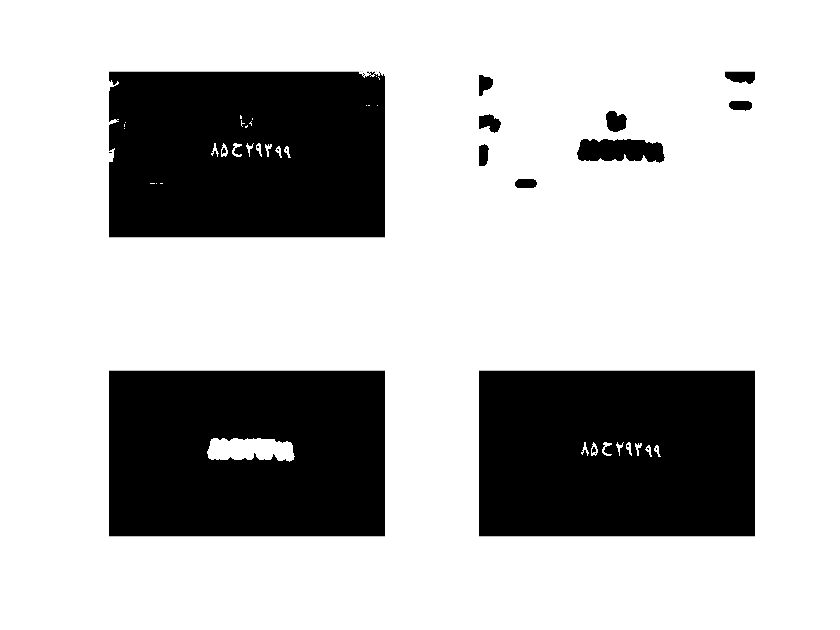


% Remove remaining wrong components
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
picture2 = bwpropfilt(~~picture2,'minorAxisLength',[5, 60]);
picture2 = bwpropfilt(picture2,'majorAxisLength',[10, 80]);
subplot(2,2,1)
imshow(picture2)
mask = bwdist(picture2); % calculate points distance
mask = imbinarize(mask,15); % hold dist < 15 points
subplot(2,2,2)
imshow(mask)
mask = bwareaopen(~mask,10000);
subplot(2,2,3)
imshow(mask)
picture3 = picture2 & mask;
subplot(2,2,4)
imshow(picture3)

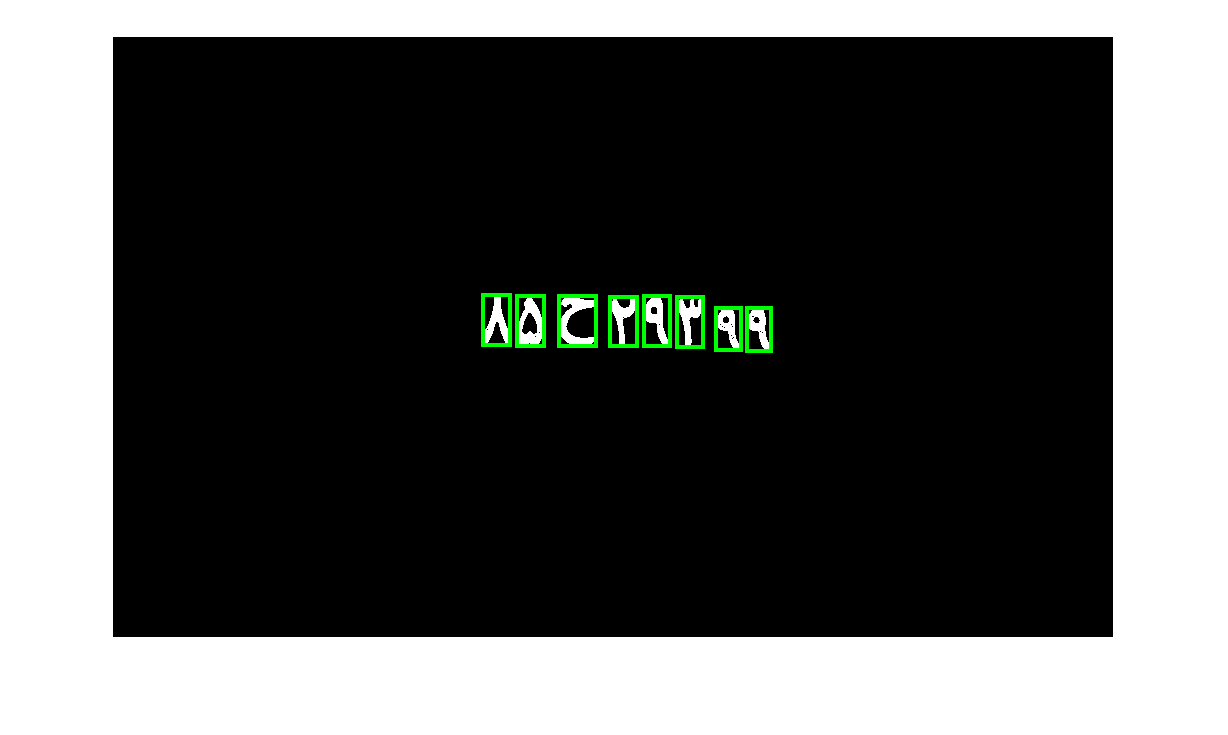


% Labeling connected components
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
imshow(picture3)
[L,Ne]=bwlabel(picture3);
propied=regionprops(L,'BoundingBox');
hold on
for n=1:size(propied,1)
    rectangle('Position',propied(n).BoundingBox,'EdgeColor','g','LineWidth',2)
end
hold off

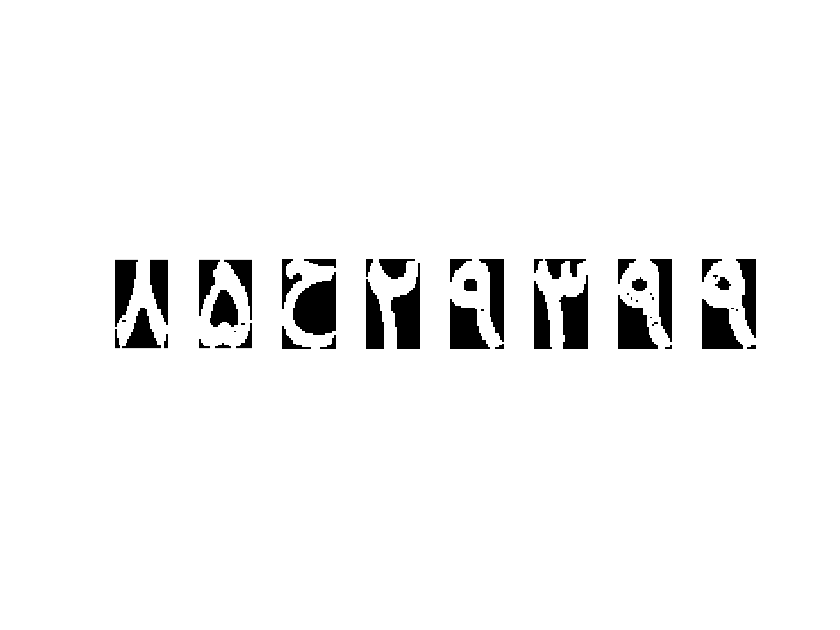


% Decision Making
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
figure
final_output=[];
t=[];
for n=1:Ne
    [r,c] = find(L==n);
    Y=picture3(min(r):max(r),min(c):max(c));
    Y=imresize(Y,[50,30]);
    subplot(1,Ne,n)
    imshow(Y)  
    
    ro=zeros(1,totalLetters);
    for k=1:totalLetters   
        ro(k)=corr2(TRAIN{1,k},Y);
    end
    [MAXRO,pos]=max(ro);
    if (MAXRO>.45) && (pos ~= 14 || n == Ne) % 0 must be appear at end
        out=cell2mat(TRAIN(2,pos));       
        final_output=[final_output,'‎',out];
    end
end



% Printing the plate
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
file = fopen('number_Plate.txt', 'wt');
fprintf(file,'%s\n',final_output);
fclose(file);
winopen('number_Plate.txt')